# Ripple Clusterig

In this document a simple approach for clustering of putative ripple episodes is illustrated.

Potentially, unsupervised clustering techniques like k means have the ability to identifiy high dimensional clusters based on the similarity of the cluster features which might not be apparent in any combination of two features alone (as can be inspected in RippleCurator)

## Import libaries

Buzcode GitHub Repo

addpath(genpath("C:\Users\Linus Meienberg\Documents\Buzcode"));
addpath(genpath('C:\Users\Linus Meienberg\Documents\MultiAreaBundleProject\RippleAnalysis'))

## Import LFP Data

lfp.filename = 'D:\INI\SemesterArbeitBaran\rTBY33\7_freely_behav_220315_145519\amplifier_ds.dat';
lfp.samplerate = 2000;
lfp.num_channels = 256;
lfp.ripple_channels = [120,85,84,86,83,87,82,88,119]; % channel number of contigous sites that show ripples
lfp.main_channel = 1; % index of the main channel for ripple detection in lfp.ripple_channels
lfp.data = detrend(double(ImporterDAT_multi(lfp.filename,lfp.num_channels,lfp.ripple_channels))'); % detrend and subsequent op require (time,channels) format
lfp.timestamps = (1:size(lfp.data,1))/lfp.samplerate;

## Filter Data

bandpass = designfilt('bandpassfir','FilterOrder',600,'StopbandFrequency1',125,'PassbandFrequency1',130,'PassbandFrequency2',245,'StopbandFrequency2',250,'SampleRate',2000);
lowpass = designfilt('lowpassfir','FilterOrder',600,'PassbandFrequency',245,'StopbandFrequency',250,'SampleRate',2000);
lfp.bandpass = filtfilt(bandpass,lfp.data);
lfp.lowpass = filtfilt(lowpass,lfp.data);

## Load Ripple Events 

Next we load the curated ripple events from our RippleCurator session

We then reject all Ripples that were marked as deleted in the previous session

inp = load("D:\INI\SemesterArbeitBaran\RippleAnalysis\rTBY33_S7\rTBY33S7_auto_ripples_curated.mat")

inp = struct with fields:
           ripple_timestamps: [8351×2 double]
    ripple_center_timestamps: [8351×1 double]
              ripple_classes: [8351×1 categorical]


ripples.clusterID = inp.ripple_classes;
ripples.timestamps = inp.ripple_timestamps;

deleted = ripples.clusterID=='deleted';
if any(deleted)
    ripples.clusterID(deleted) = [];
    ripples.timestamps(deleted,:) = [];
end

ripples.n = size(ripples.timestamps,1);

## Load Feature Table 

Import the extracted features for the ripple episodes. We will search for clusters in this feature space.

inp = load("D:\INI\SemesterArbeitBaran\RippleAnalysis\rTBY33_S7\rTBY33S7_auto_features_extended.mat")

inp = struct with fields:
    featureTable: [8351×41 table]


% reject entries that belong to deleted ripples
featureTable(deleted,:) = [];
ripples.centers = table2array(featureTable(:,'center Timepoint'));


## Preprocess data for clustering

For clustering we exclude certain attributes from the feature table such as 

- the event duration since it was determined by different detection algorithms and is inconsistent and unreliable

- the center timepoint of each ripple since it is not relevant for ripple similarity

- the linear discriminants which are linear combinations of other features in the feature Table

We then normalize the features such that they are all zero centered and have unit variance. This ensures even contribution of the features to the overall distance or 'similarity' metric used to assign observations to clusters.

cluster_variables = 2:38; % do not include amplitude, center Timepoint, false positive vs Ripple and SPWR vs Ripple for clustering
cluster_features = table2array(featureTable(:,cluster_variables));
cluster_features = zscore(cluster_features); % center and scale each feature

Using a dimensionality reduction technique like tSNE we can try to visualize the neighbourhood relationships of our observations in feature space. If a cluster structure exists they likely extend over neighbouring points in this plot.

Initially, show the distribution of class labels that was imported from RippleCurator.

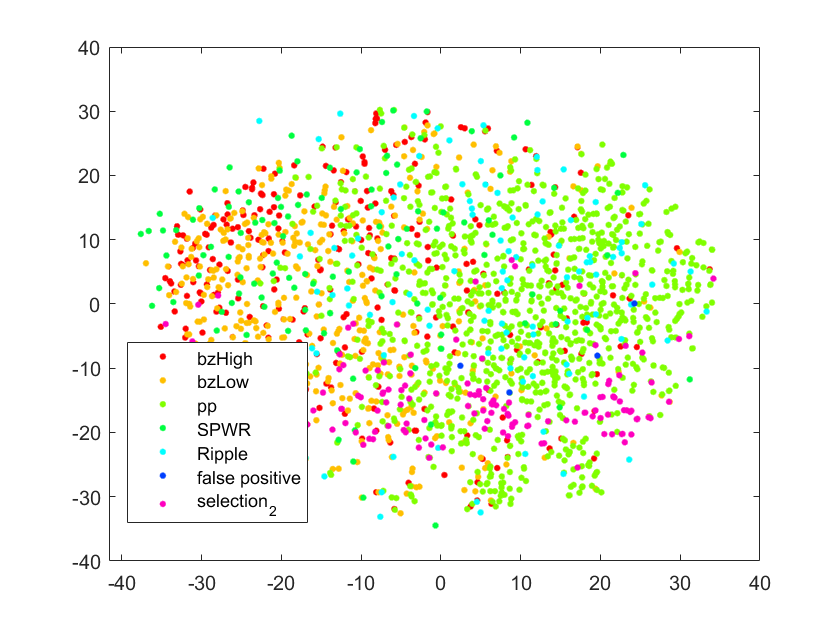

embedding = tsne(cluster_features);
figure();
gscatter(embedding(:,1),embedding(:,2),ripples.clusterID,[],[],10)

## Apply k-means clustering

We can now apply a clustering technique such as k-means to search for cluster structure that might have escaped our previous inspection of the dataset.

Here we use k-means clusterings for 2 to 5 clusters.

We can inspect cluster quality visualy in the tSNE embedding or using the silhouette plot.

*"A silhouette plot displays a measure of how close each point in one cluster is to points in the neighboring clusters. This measure ranges from 1 (indicating points that are very distant from neighboring clusters) through 0 (points that are not distinctly in one cluster or another) to –1 (points that are probably assigned to the wrong cluster)" - matlab documentation: stats/k-means-clustering*

ans = "n clusters = 2"

Replicate 1, 12 iterations, total sum of distances = 70886.1.
Replicate 2, 13 iterations, total sum of distances = 70886.4.
Replicate 3, 8 iterations, total sum of distances = 70886.4.
Best total sum of distances = 70886.1


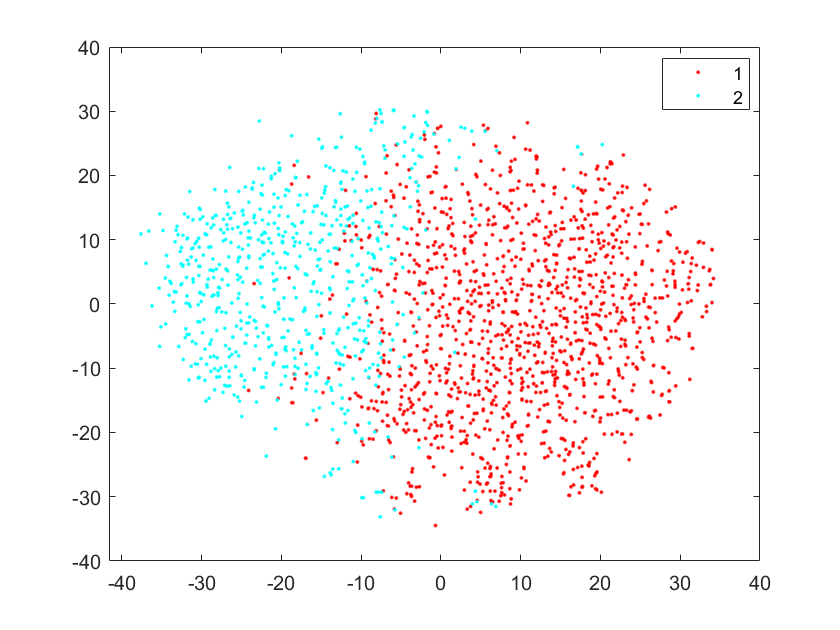

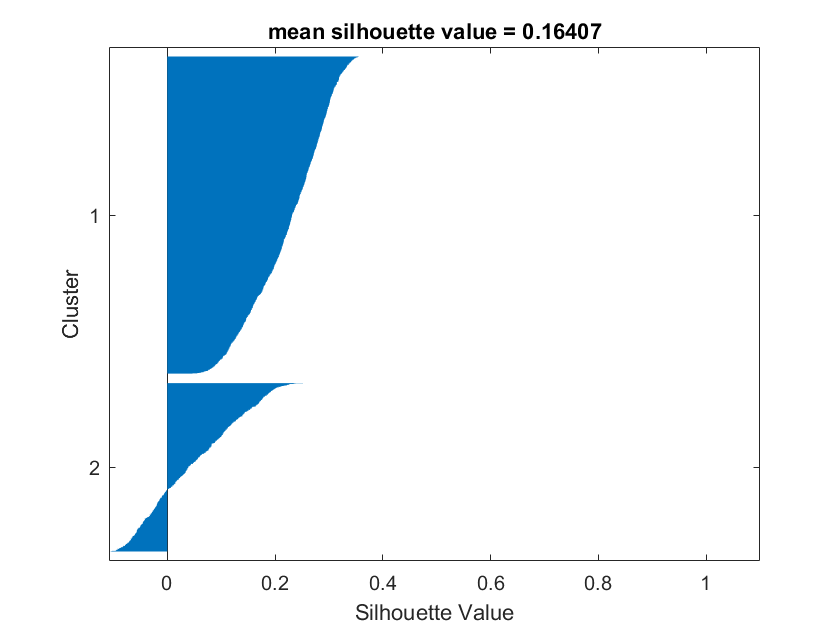

ans = "n clusters = 3"

Replicate 1, 18 iterations, total sum of distances = 67742.5.
Replicate 2, 16 iterations, total sum of distances = 67546.8.
Replicate 3, 52 iterations, total sum of distances = 67752.
Best total sum of distances = 67546.8


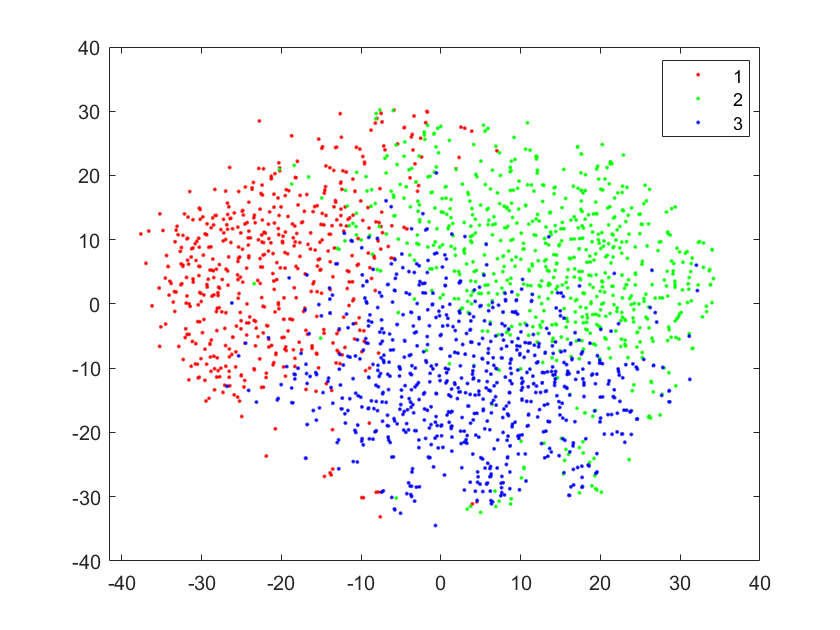

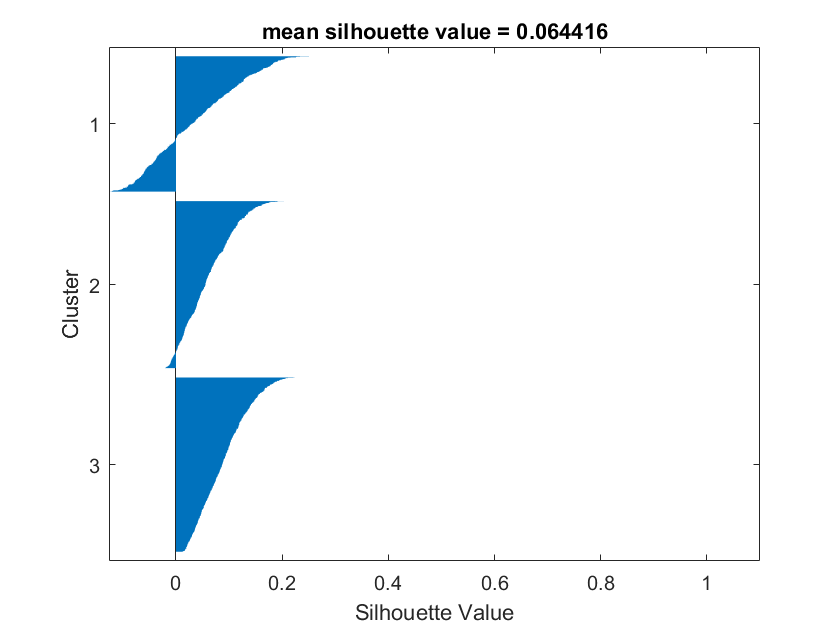

ans = "n clusters = 4"

Replicate 1, 28 iterations, total sum of distances = 64891.3.
Replicate 2, 27 iterations, total sum of distances = 64888.8.
Replicate 3, 39 iterations, total sum of distances = 64912.
Best total sum of distances = 64888.8


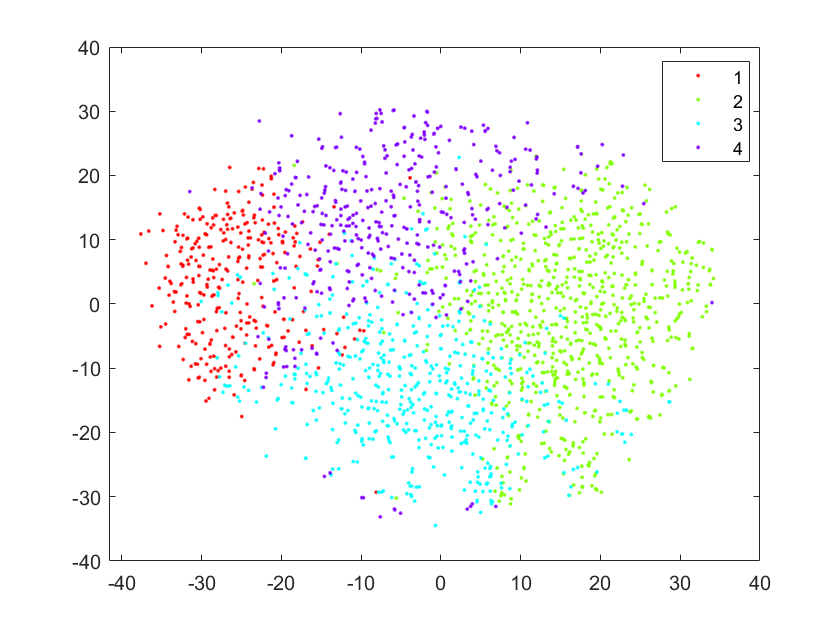

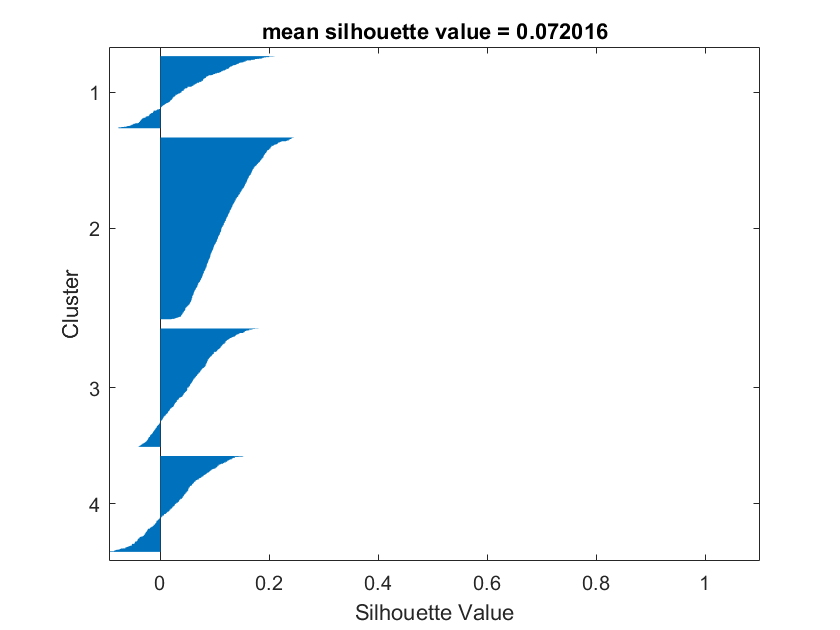

ans = "n clusters = 5"

Replicate 1, 30 iterations, total sum of distances = 63328.1.
Replicate 2, 19 iterations, total sum of distances = 63410.8.
Replicate 3, 48 iterations, total sum of distances = 63287.6.
Best total sum of distances = 63287.6


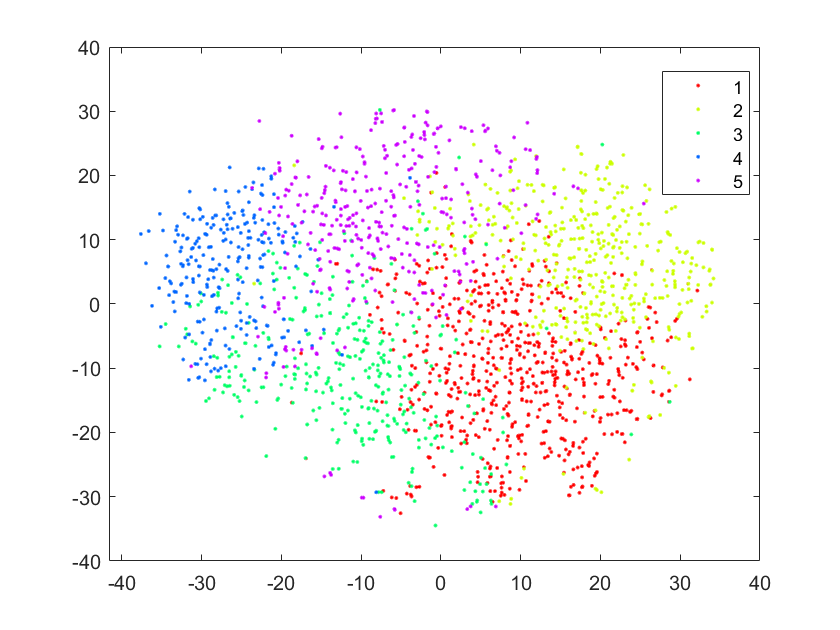

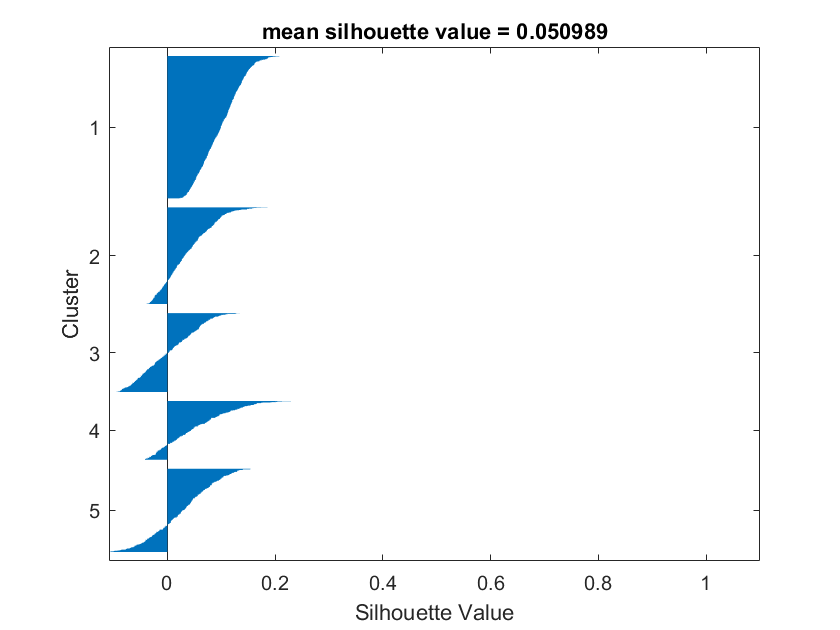

% apply clustering method to data

for n_clusters = 2:5
    "n clusters = " + n_clusters
    [idx, centroids, sumd ] = kmeans(cluster_features,n_clusters,'Display','final','Replicates',3);
    figure() % visualize partition of embedding
    gscatter(embedding(:,1),embedding(:,2),idx)

    figure() % display silhouette plot
    [silh,h] = silhouette(cluster_features,idx,'Euclidean');
    xlabel('Silhouette Value')
    ylabel('Cluster')
    title("mean silhouette value = " + mean(silh))
end

For interactive inspection of the clustering result we can also use the RippleCurator.

To inspect the neighbourhood relationships of the ripples, add the two tSNE embedding dimensions to the feature table.

The result of the clustering is converted into class labels for each ripple.

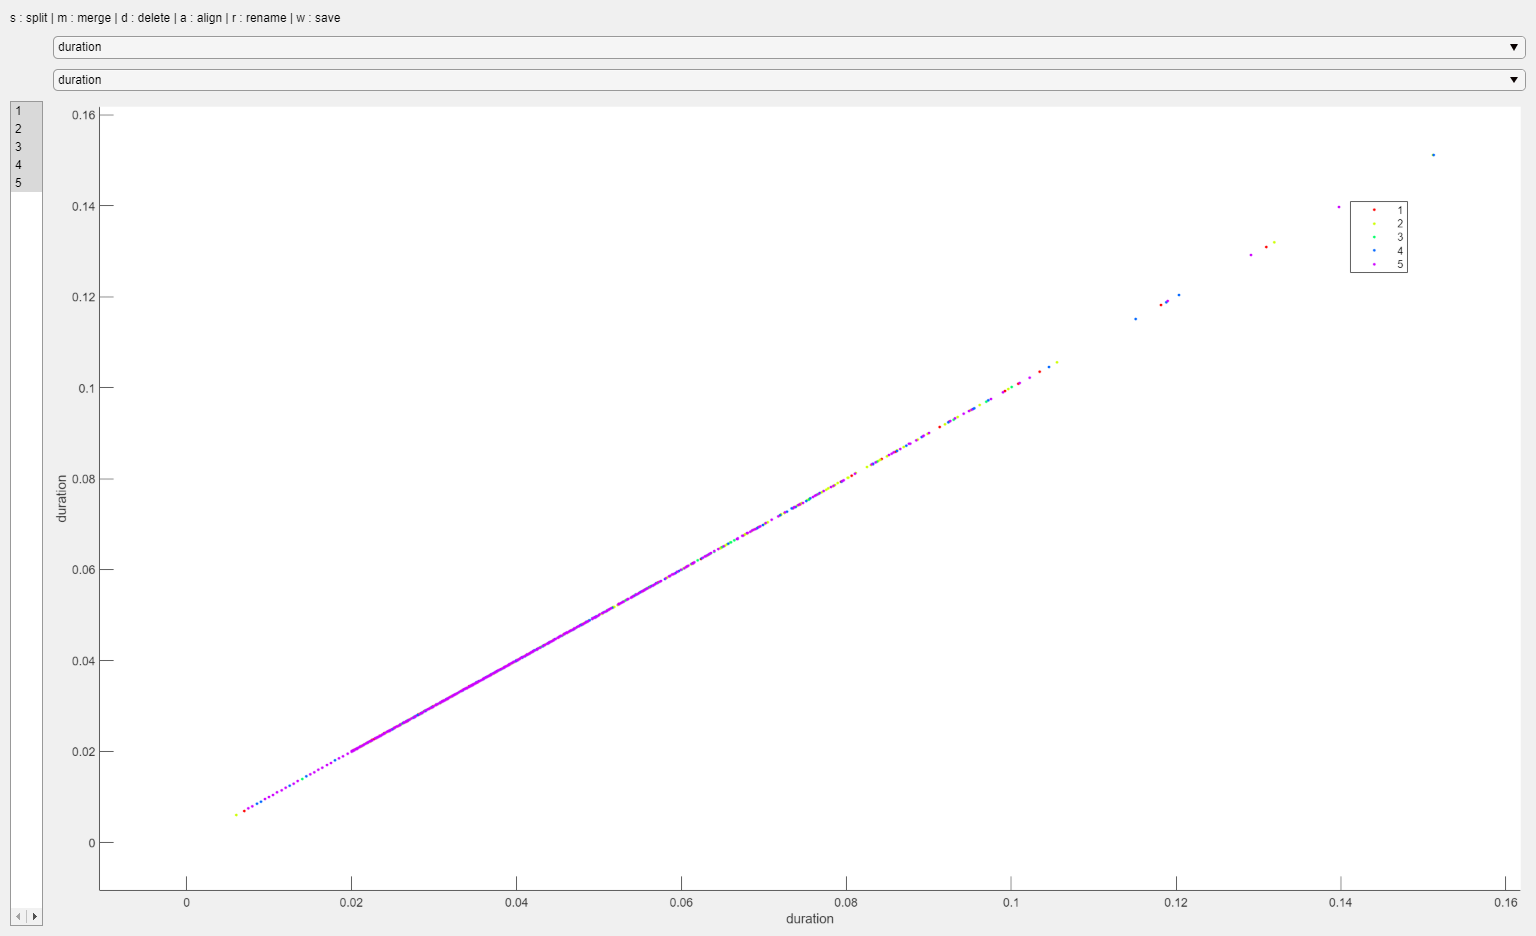

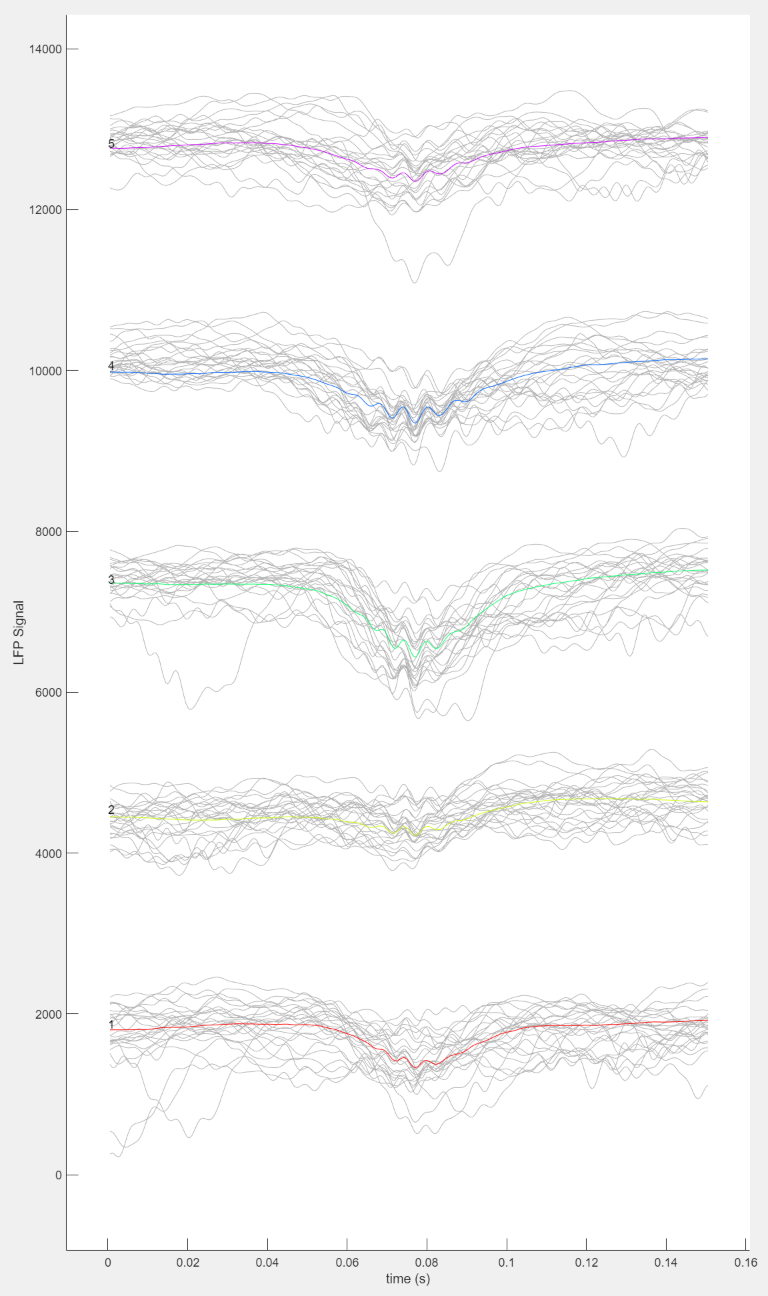

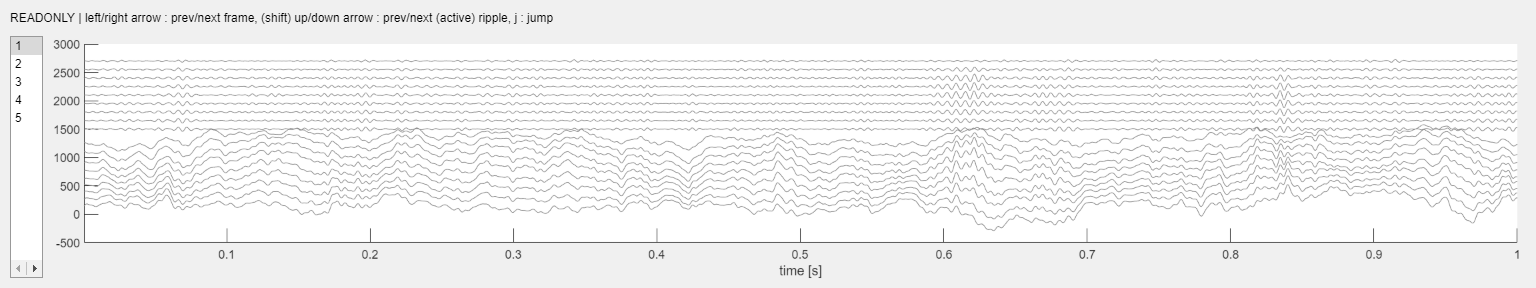

c =   RippleCurator with properties:

            lfp_samplerate: 2000
                lfp_signal: [7300724×9 double]
         ripple_timestamps: [2232×2 double]
       ripple_center_seeds: [2232×1 double]
            ripple_centers: [2232×1 double]
          ripple_clusterID: [2232×1 categorical]
      ripple_feature_table: [2232×43 table]
                  ripple_n: 2232
            feature_window: [1×1 Figure]
       feature_instruction: [1×1 Label]
         feature_Selector1: [1×1 DropDown]
         feature_Selector2: [1×1 DropDown]
    feature_clusterListbox: [1×1 ListBox]
              feature_axes: [1×1 UIAxes]
            cluster_window: [1×1 Figure]
              cluster_axis: [1×1 UIAxes]
                lfp_viewer: [1×1 Figure]
                 cluster_n: 5
            cluster_labels: {5×1 cell}
            cluster_colors: [5×3 double]
            rippleEpisodes: [2232×301 double]
           default_messag

% inspect the result of your favourite clustering in rippleCurator
featureTable(:,'tSNE1') = table(embedding(:,1));
featureTable(:,'tSNE2') = table(embedding(:,2));
clusters = categorical(idx);
c = RippleCurator(lfp.samplerate,lfp.lowpass,ripples.timestamps,ripples.centers,clusters,featureTable,lfp.bandpass);